clear;clc; close all;% clear workspace and command window

if ~exist('MATLABCodeCNNSVM.zip','file')
    disp('Downloading file (218 MB)...');
    URL = 'https://melbourne.figshare.com/ndownloader/files/24726374';
    websave('MATLABCodeCNNSVM.zip',URL);
else
    disp('Zip file exists')
end

Zip file exists


unzip('MATLABCodeCNNSVM.zip')
disp('Unzipped files')
addpath('FinalCodeSVM/') 
addpath('FinalCodeSVM/SupportingFunctions/') 

### Visualise PKLot dataset

PKLot dataset contains 12000+ CCTV images and 695,000+ segmented parking slot images. 

The occupancy was manually generated. For the scope of the tutorial, we sampled 3000 parking slot images.

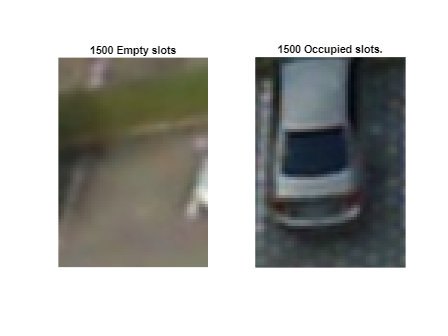

% Visualise the segmented images of PKLot dataset 
% (We sampled 1500 occupied and 1500 Empty spaces)
PKLotEmpty = imresize(imread(...
    'FinalCodeSVM\PKLotSegmentedSampled\Empty\2012-09-11_15_45_57#004.jpg'), [70 50]);
PKLotOccupied = imresize(imread(...
    'FinalCodeSVM\PKLotSegmentedSampled\Occupied\2012-09-11_15_36_32#100.jpg'), [70 50]);
figure
subplot(1,2,1)
imshow(PKLotEmpty);
title ('1500 Empty slots')
subplot(1,2,2)
imshow(PKLotOccupied);
title ('1500 Occupied slots.')

### Visualise Barry street data

Visualise Barry street (100 images with 28 parking lots). This is our test data, and we want to identify the parking slots automatically, and subsequently perform occupancy detection. Ground truth and parking slot annotations are for evaluation purpose.

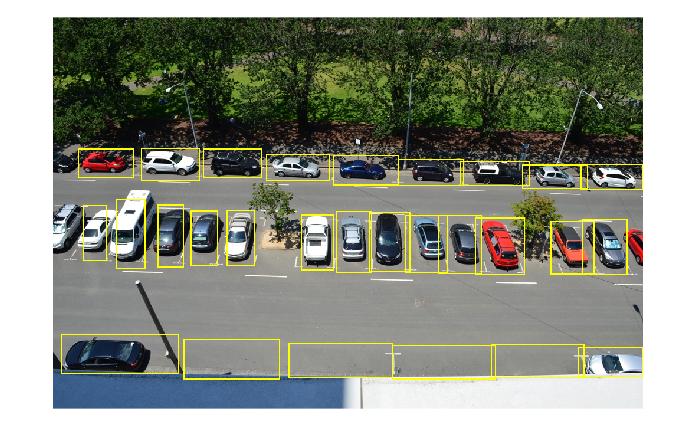

% Load image to train.
BarryStreetImage = imread('FinalCodeSVM\BarryStreetData\DSC_0455.JPG');

% load the parking slot markings and occupancy from ground truth image
load('GroundTruthBarryStreet.mat');

% Visualise Barry Street
figure
BarryStreetImageAnn = insertShape(BarryStreetImage,'rectangle',ParkingSlots,...
    'LineWidth', 2);
imshow(BarryStreetImageAnn);

This concludes the dataset visualisation.

# Tutorial - Extract features from a pre-trained network to train a binary SVM (CPU Friendly)

#### Training can be done with CPU and total training time is under 7 minutes

The following snippet will load a pre-trained Resnet50 CNN and extract image features from PKLot dataset which will be subsequently be used to train a cubic SVM classifier with 5-fold cross validation. The trained model will be tested with Barry street dataset for evaluation.

clear;clc;close all;

### Extract features of PKLot images using pre-trained Resnet50 and train an SVM classifier

Extract the features using the CNN. This might take 6 minutes to run on CPU or a couple of seconds on GPU. For convinience we provide the training matrix that is loaded by default. The following line should be changed to false do the process online.

LoadTrainingMatrix = true;

if (LoadTrainingMatrix == false)
    
    % load the feature extractor that is a pre-trained ResNet50 CNN
    load('Resnet50FeatureExtractor.mat');

    % select the last layer before classification to extract the features
    layer = 'fc1000';

    % fetch the input image size of the CNN for resizing the cropped images 
    inputSize = net.Layers(1).InputSize;

    % setting up the paths of the segmented empty and occupied parking spots
    occupydata = dir(fullfile(pwd,...
        'FinalCodeSVM\PKLotSegmentedSampled\Occupied\', '*.jpg'));
    occupydata = {occupydata.name}';
    emptydata = dir(fullfile(pwd,...
        'FinalCodeSVM\PKLotSegmentedSampled\Empty\', '*.jpg'));
    emptydata = {emptydata.name}';

    % initialise the training matrix that will serve as an input to the SVM
    % classifier containing the ground truth labels
    training_matrix= zeros(length(occupydata)+ length(emptydata), 1001);
    labels = cell(length(occupydata)+ length(emptydata),1);

    % extract features of 1500 occupied parking slots
    tic
    for occupyImageIndex =1:length (occupydata)
        OccupyIm = imread (fullfile ( ...
            pwd,'FinalCodeSVM\PKLotSegmentedSampled\Occupied\',...
            occupydata{occupyImageIndex}));
        OccupyIm = imresize(OccupyIm, inputSize(1:2));
        featuresOccupy = activations(net,OccupyIm,layer,'OutputAs','rows');
        training_matrix(occupyImageIndex,1:1000) = featuresOccupy;
        training_matrix(occupyImageIndex,1001)=1;
        labels{occupyImageIndex} = 'Occupied';
    end
    toc

    %Extract features of 1500 empty parking slots
    for emptyImageIndex =1:length (emptydata)
        EmptyIm = imread (fullfile ( pwd,'FinalCodeSVM\PKLotSegmentedSampled\Empty\',...
            emptydata{emptyImageIndex}));
        EmptyIm = imresize(EmptyIm, inputSize(1:2));
        featuresEmpty = activations(net,EmptyIm,layer,'OutputAs','rows');
        training_matrix(occupyImageIndex+emptyImageIndex,1:1000) = featuresEmpty;
        training_matrix(occupyImageIndex+emptyImageIndex,1001)=0;
        labels{occupyImageIndex+emptyImageIndex}='Empty';
    end
else
    load('trainingMatrix.mat');
    disp('Training matrix loaded')
end

Training matrix loaded


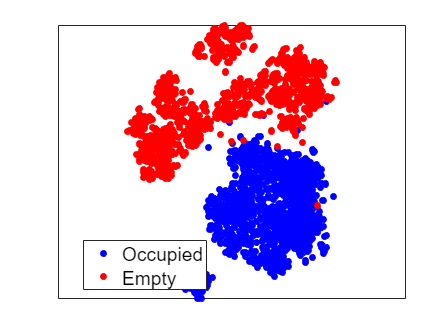


% visualise the features extracted by the CNN with t-SNE algorithm
Y = tsne(training_matrix(:,1:1000));
figure
h= gscatter(Y(:,1),Y(:,2), labels, '', 'o');
set(h(1), 'Color', 'b', 'MarkerFaceColor', 'b');
set(h(2), 'Color', 'r', 'MarkerFaceColor', 'r');
set(gca,'FontSize',20)
axis equal;
set(gca,'xtick',[], 'ytick', [])


% train the cubic SVM classifier with 5-fold cross validation, should take
% 6 seconds to train the classifier

tic
% using 5 fold cross validation in the model
[trainedClassifier, validationAccuracy, validationPredictions] =...
    trainClassifier(training_matrix); 
toc

Elapsed time is 3.264077 seconds.


disp('Training finished for the SVM classifier')

Training finished for the SVM classifier



% display the cross-validation accuracy of the trained classifier for the training data
fprintf('The validation accuracy of the classifier %f %%.\n',validationAccuracy*100);

The validation accuracy of the classifier 99.866667 %.


### Test the classification accuracy of the classifier with Barry street dataset

In this section we take images of Barry street dataset, crop out all the parking slots of each image and extracts features using the CNN. This might take 8 minutes on CPU or a couple of seconds on GPU. For convinience we provide the testing matrix that is loaded by default. To run online please change the next code line to true.


TestOnline = false;

load('GroundTruthBarryStreet.mat') % load the ground truth to evaluate accuracy

% setup the path to Barry street dataset
imageName = dir(fullfile(pwd,'FinalCodeSVM\BarryStreetData\', '*.JPG'));
imageName = {imageName.name}';

% load the feature extractor that is a pre-trained ResNet50 CNN
load('Resnet50FeatureExtractor.mat');

% set the feature extraction layer
layer = 'fc1000';

% fetch the input image size of the CNN for resizing the cropped images 
inputSize = net.Layers(1).InputSize;

if (TestOnline == true)
    tic
    count =1;
    for n=1:length(imageName)
        BarryStreetImage = imread (fullfile (...
            pwd, 'FinalCodeSVM\BarryStreetData\', imageName{n}));
        for m=1:length(Occupancy(:,1))
            % crop out individual parking slots
            cropImage{count} = imcrop(BarryStreetImage, ParkingSlots(m,:)); 
            
            % Process ground truth to cell
            if Occupancy (m,n)==1
                AnnotationTable{count} = 'Occupied';
            else
                AnnotationTable{count} = 'Empty';
            end
            % resize the crops to input size of the CNN
            imdsIm = imresize(cropImage{count}, inputSize(1:2)); 
            
             % calculate activations
            features(count,:) = activations(net,imdsIm,layer,'OutputAs','rows');
            
            % SVM predictions
            [YPred(count), probs(count,:)] =...
                trainedClassifier.predictFcn(features(count,:)); 
            
            % Process predictions to cells
            if YPred(count) == 1
                YpredClass {count} = 'Occupied' ;
            else
                YpredClass {count} = 'Empty' ;
            end
            count=count+1;
        end
    end
    toc
else
    load('TestFeatures.mat');
    disp('Test Features loaded');
    tic
    % perform prediction with SVM classifier
    [YPred, probs] = trainedClassifier.predictFcn(features); % SVM predictions
    YPred = YPred'; % transpose matrix to serve input to plotconfusion function
    
    count =1;
    for n=1:length(imageName)
        for m=1:length(Occupancy(:,1))
            
            % Process predictions to cells
            if YPred(count) == 1
                YpredClass {count} = 'Occupied' ;
            else
                YpredClass {count} = 'Empty' ;
            end
            count=count+1;
        end
    end
    toc
end

Test Features loaded


Elapsed time is 0.376609 seconds.


testAccuracy = mean(Occupancy(:) == YPred');
fprintf('The test accuracy of the classifier %f %%.\n',testAccuracy*100);

The test accuracy of the classifier 98.892857 %.


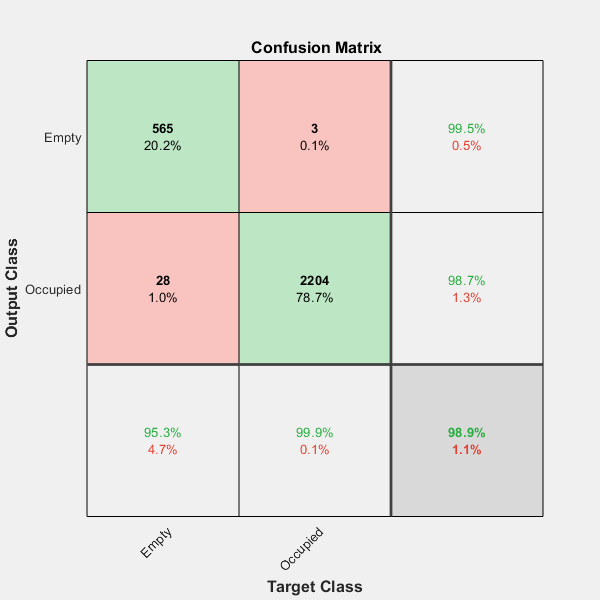

figure
plotconfusion (categorical(AnnotationTable'), categorical(YpredClass'))

## Visualise some wrongly classified slots

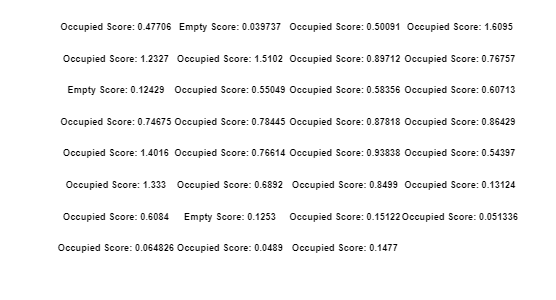


WrongSlots = find(categorical(YpredClass) ~= AnnotationTable);
figure
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
for n=1:length(WrongSlots)
    subplot(8,4,n);
    imshow(cropImage{WrongSlots(n)});
    str = [char(YpredClass(WrongSlots(n)))...
        ' Score: ' num2str(max(probs(WrongSlots(n),:)))];
    title(str);
end

### Visualise the occupancy

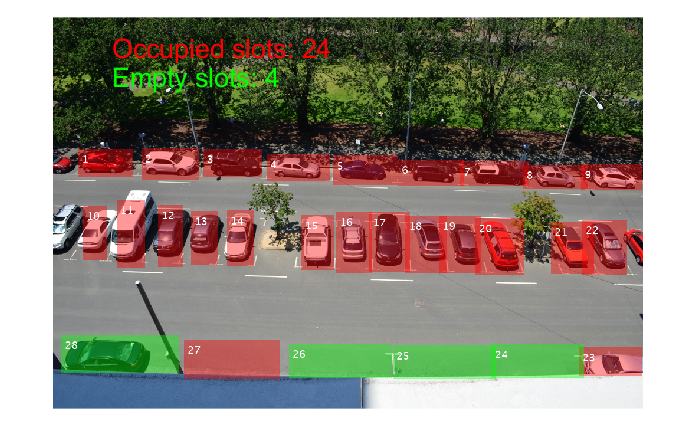

figure
AnnotatedImage = imread("FinalCodeSVM\BarryStreetData\DSC_0420.JPG");
%AnnotatedFinal;
emptySlots = 0;
occupiedSlots =0;

emptySlotArray = [];
occupiedSlotsArray = [];

for n=1:28
    if YpredClass(n) == "Empty"
       AnnotatedImage =  insertShape(AnnotatedImage,'FilledRectangle',...
    ParkingSlots(n,:),'LineWidth', 1, 'Color', "green", 'Opacity', 0.4);
       AnnotatedImage = insertText(AnnotatedImage, [ParkingSlots(n,1) ParkingSlots(n,2)], ...
           n,"FontSize",18,"TextColor","white","BoxOpacity",0.0);
       emptySlotArray = [emptySlotArray, n];
    emptySlots = emptySlots + 1;
    else
       AnnotatedImage =  insertShape(AnnotatedImage,'FilledRectangle',...
    ParkingSlots(n,:),'LineWidth', 1, 'color', "red", 'Opacity', 0.4);
       AnnotatedImage = insertText(AnnotatedImage, [ParkingSlots(n,1) ParkingSlots(n,2)], ...
           n,"FontSize",18,"TextColor","white","BoxOpacity",0.0);
       occupiedSlotsArray = [occupiedSlotsArray, n];
    occupiedSlots = occupiedSlots + 1;
    end


    %disp(ParkingSlots(n,:));
    %disp(ParkingSlots(n,2));
end
imshow(AnnotatedImage)
text (100, 50,['Occupied slots: ' num2str(occupiedSlots)],'Color', 'red','FontSize',20);
text (100, 100,['Empty slots: ' num2str(emptySlots)],'Color', 'green','FontSize',20); 

disp(occupiedSlotsArray);

  Columns 1 through 14

     1     2     3     4     5     6     7     8     9    10    11    12    13    14

  Columns 15 through 24

    15    16    17    18    19    20    21    22    23    27



disp(emptySlotArray);

    24    25    26    28




httpsUrl = 'http://localhost:5000/user/signin';
user(1).email = 'dasundurage@gmail.com';
user(1).password = '123456';
options = weboptions('ContentType', 'json');
responseEmployee = webwrite(httpsUrl, user, options);
token = responseEmployee.token;

groundTruthLabeler;

'groundTruthLabeler' requires Automated Driving Toolbox.